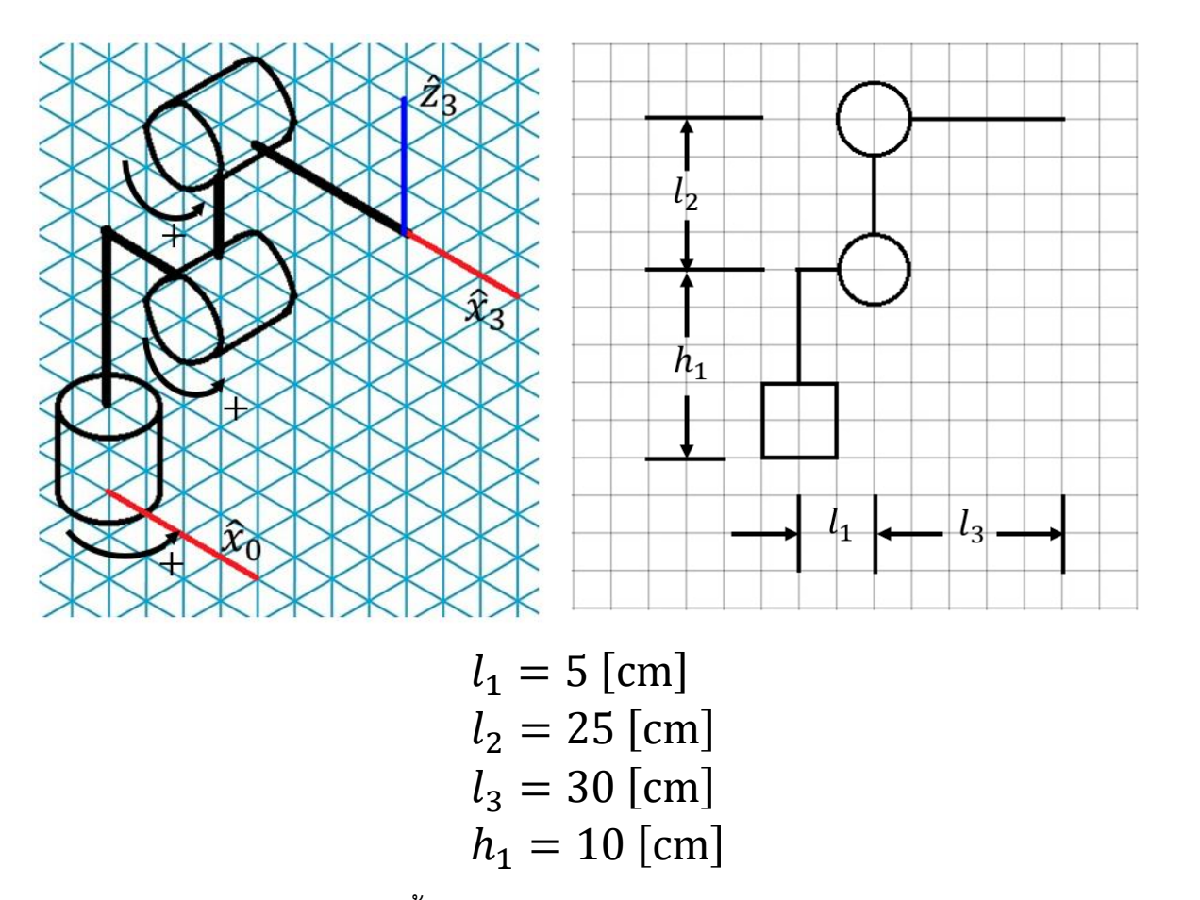

**input**

    .txt:    robot command = (2,n)

    .txt:    via_point_info = (3,m) // m = size of command via_points_task set in task space

**local variable**

    command = (1,n) L:0,J:1 

    via_point_task = (3,n) 

    via_point_joint_all = (3,n,4)

    via_point_joint = (3,n)

**step(function)**

readVariable => task2jointConversion =>  select optimal joint => gen C

**readVariable:** write .txt + return: via_point_task = (3,n), command = (1,n) L:0,J:1 

      Description: read variable

**task2jointConversion:** third dimension = all possible via point in joint space + return alert 0: cant access, 1: accessable; via_point_joint

      Description: check possible access + convert task to joint

p = [0.4, 0.02, 0.5;
     0.1, 0.2 , 0.3;
     0.06,0.08, 0.3];
[alert, via_point_joint] = task2jointConversion(p)

alert = 0

via_point_joint =      0     0     0
     0     0     0
     0     0     0
